# 清理并设置MATLAB文件夹

currentFolder = pwd;
splitted_str = strsplit(currentFolder,'\');
index = contains(splitted_str,'CableSSB-zh');
if ~any(index)
    error('请进入一个在''CableSSB-zh''内的文件夹')
end
mainpath = '';
for i=1:length(splitted_str)
    if index(i)
        path = join(splitted_str(1:i),'\');
        break
    else
        continue
    end
end
MainPath = genpath(path{1});
addpath(MainPath)

clear all
clc

# 建立斜拉悬索协作体系桥梁模型

original_bridge = CableStayedSuspension_Bridge;
original_bridge.build;

Is building a Cable-Stayed Suspension Bridge...


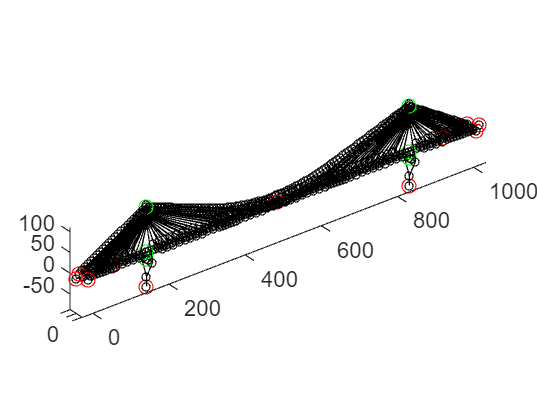

ans =   Figure (1) - 属性:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [440 338 560 420]
       Units: 'pixels'

  显示 所有属性


original_bridge.plot

output_method = OutputToAnsys(original_bridge,"JobName",'OrginalModel',...
    'AnsysPath','C:\Program Files\ANSYS Inc\ANSYS Student\v232\ansys\bin\winx64\MAPDL.exe',...
    'WorkPath','C:\Users\11440\Desktop\usage\CableSuspensionBridge\CS_Bridge',...
    'MacFilePath','C:\Users\11440\Desktop\usage\CableSuspensionBridge\CS_Bridge\main.mac',...
    'ResultFilePath','C:\Users\11440\Desktop\usage\CableSuspensionBridge\CS_Bridge\result.out');
original_bridge.OutputMethod = output_method;
original_bridge.output

# 建立无索模型，并优化其最小弯曲应变能

% 建立无索模型（用于优化弯曲应变能，不可以直接使用ANSYS运行）
nocable_bridge = NoCable_Bridge(original_bridge);
nocable_bridge.build

Is building a Brigde without Cable System...


output_method = OutputToAnsys(nocable_bridge,"JobName",'NonCableModel',...
    'AnsysPath','C:\Program Files\ANSYS Inc\ANSYS Student\v232\ansys\bin\winx64\MAPDL.exe',...
    'WorkPath','C:\Users\11440\Desktop\usage\CableSuspensionBridge\NC_Bridge',...
    'MacFilePath','C:\Users\11440\Desktop\usage\CableSuspensionBridge\NC_Bridge\main.mac',...
    'ResultFilePath','C:\Users\11440\Desktop\usage\CableSuspensionBridge\NC_Bridge\result.out');
nocable_bridge.OutputMethod = output_method;
[FEModel,isEquationCompleted] = nocable_bridge.getFiniteElementModel;

Is getting Finite Element Model from ANSYS...



% 优化弯曲应变能
nocable_bridge.optimBendingStrainEnergy('MaxIter',1,'DiffMinChange',1e4);

% 结果呈现
Map_Pz = nocable_bridge.Result_Iteration.Iter_Pz;
max_iter = nocable_bridge.Iter_Optimization;
Pz_final = Map_Pz(max_iter);
X_Pz = nocable_bridge.OriginalBridge.getSortedGirderPointXCoord([nocable_bridge.OriginalBridge.findStructureByClass('Hanger'),nocable_bridge.OriginalBridge.findStructureByClass('StayedCable')]);
bar(X_Pz,Pz_final)

% 验证无索模型（可以直接使用ANSYS运行）
output_method = OutputToAnsys(nocable_bridge,"JobName",'NonCableModel',...
    'AnsysPath','C:\Program Files\ANSYS Inc\ANSYS Student\v232\ansys\bin\winx64\MAPDL.exe',...
    'WorkPath','C:\Users\11440\Desktop\usage\CableSuspensionBridge\Optimed_NC_Bridge',...
    'MacFilePath','C:\Users\11440\Desktop\usage\CableSuspensionBridge\Optimed_NC_Bridge\main.mac',...
    'ResultFilePath','C:\Users\11440\Desktop\usage\CableSuspensionBridge\Optimed_NC_Bridge\result.out');
nocable_bridge.OutputMethod = output_method;

# 求解初索力：运行AnsysTask

% 运行AnsysTask
time_before = datetime('now');
[status,cmdout] = AnsysTask(nocable_bridge)

status = 8


cmdout =

  空的 0×0 char 数组



time_after = datetime('now');
time_diff = time_after - time_before;

# 求解初索力：工具程序toolkit

function [bridge,data_container] = outputTask(obj)
    bridge = obj.clone();
    data_container = DataContainer();
    % 主缆找形、根据最优设计竖向力Pz_final计算主缆线形和内力、吊索内力
    Pz_final = bridge.Result_Iteration.Iter_Pz(bridge.Iter_Optimization);
    Y_0 = bridge.solveCableShape(Pz_final);
    % 最优设计竖向力Pz_final计算斜拉索内力
    X_Pz = bridge.XCoordOfPz;
    for i=1:length(bridge.ReplacedStayedCable)
        stayed_cable = bridge.ReplacedStayedCable(i);
        Point_Bottom = stayed_cable.findGirderPoint();
        X_Bottom = [Point_Bottom.X];
        P_girder_z = zeros(1,length(X_Bottom));
        for j=1:length(X_Pz)
            index = abs(X_Pz(j)-X_Bottom) < 1e-5;
            P_girder_z(index) = Pz_final(j);
        end
        stayed_cable.getP(P_girder_z);
    end
    % 复制Maps
    Maps_clone = cloneMaps(bridge.FiniteElementModel.Maps);
    bridge.FiniteElementModel = bridge.FiniteElementModel.clone();
    bridge.FiniteElementModel.Maps = Maps_clone;
    % 输出BaseModel
    outputBaseModel(bridge)
    % 在MATLAB中恢复为CableSystem
    resumeCableSystem(bridge)
    % % 输出CableSystem
    outputCableSystem(bridge);
    % 根据设计竖向力的顺序，排列与之相关的
    Map_Line2Element = bridge.FiniteElementModel.Maps.Line2Element;
    num_elem = [];
    index_line2elem = [];
    L_elem = [];
    E = [];
    Iyy = [];
    Izz = [];
    Comp_y = [];
    Comp_z = [];
    StrucutreList = bridge.ReplacedGirder;
    for i=1:length(StrucutreList)
        structure = StrucutreList(i);
        lines = structure.Line;
        [delta_x,delta_y,delta_z] = lines.DeltaLength();
        L_line = sqrt(delta_x.^2 + delta_y.^2 + delta_z.^2);
        E_structure = structure.Material.MaterialData.E;
        [~,comp_y,comp_z] = getLocalCoordSystemComponent(lines);
        for j=1:length(lines)
            line = lines(j);
            elem = Map_Line2Element(line.Num);
            count_elem = length(elem);
            num_elem(1,end+1:end+count_elem) = elem;
            index_line2elem(1,end+1:end+count_elem) = line.Num;
            L_elem(1,end+1:end+count_elem) = L_line(j)/count_elem+zeros(1,count_elem);
            E(1,end+1:end+count_elem) = E_structure+zeros(1,count_elem);
            Iyy(1,end+1:end+count_elem) = structure.Section(j).SectionData.Iyy+zeros(1,count_elem);
            Izz(1,end+1:end+count_elem) = structure.Section(j).SectionData.Izz+zeros(1,count_elem);
            Comp_y(1,end+1:end+count_elem) = comp_y(j)+zeros(1,count_elem);
            Comp_z(1,end+1:end+count_elem) = comp_z(j)+zeros(1,count_elem);
        end
    end
    StrucutreList = bridge.ReplacedTower;
    for i=1:length(StrucutreList)
        structure = StrucutreList(i);
        lines = structure.Line;
        [delta_x,delta_y,delta_z] = lines.DeltaLength();
        L_line = sqrt(delta_x.^2 + delta_y.^2 + delta_z.^2);
        E_structure = structure.Material.MaterialData.E;
        [~,comp_y,comp_z] = getLocalCoordSystemComponent(lines);
        for j=1:length(lines)
            line = lines(j);
            elem = Map_Line2Element(line.Num);
            count_elem = length(elem);
            num_elem(1,end+1:end+count_elem) = elem;
            index_line2elem(1,end+1:end+count_elem) = line.Num;
            L_elem(1,end+1:end+count_elem) = L_line(j)/count_elem+zeros(1,count_elem);
            E(1,end+1:end+count_elem) = E_structure+zeros(1,count_elem);
            Iyy(1,end+1:end+count_elem) = structure.Section(j).SectionData.Iyy+zeros(1,count_elem);
            Izz(1,end+1:end+count_elem) = structure.Section(j).SectionData.Izz+zeros(1,count_elem);
            Comp_y(1,end+1:end+count_elem) = comp_y(j)+zeros(1,count_elem);
            Comp_z(1,end+1:end+count_elem) = comp_z(j)+zeros(1,count_elem);
        end
    end
    I = Iyy.*Comp_y + Izz.*Comp_z;
    bridge.outputAnsysIPC(num_elem);
    workspace = bridge.OutputMethod.WorkPath;
    % 运行BaseModel
    obj.run('JobName','BaseModel',...
            'MacFilePath',fullfile(workspace,'main_Base.mac'),...
            'ResultFilePath',fullfile(workspace,'Result_BaseModel.out'));

    % 存储数据
    data_container.Data.NoCableBridge = obj;
    data_container.Data.bridge = bridge;
    data_container.Data.workspace = workspace;
    data_container.Data.Pz_target = Pz_final;
    data_container.Data.Y_0 = Y_0;
    data_container.Data.Map_Pz_solved = containers.Map("KeyType",'double','ValueType','any');
    data_container.Data.count_ObjFunc = 0;
    data_container.Data.L_elem = L_elem;
    data_container.Data.E = E;
    data_container.Data.I = I;
    data_container.Data.Comp_y = Comp_y;
    data_container.Data.Comp_z = Comp_z;
    data_container.Data.index_line2elem = index_line2elem;
end

function  [x,fval,exitflag,output] = OptimTask(data_container)
    Pz_target = data_container.Data.Pz_target;
    workspace = data_container.Data.workspace;
    MaxIter = data_container.Data.MaxIter;

    % 转换设计变量
    data_container.Data.original_var = Pz_target;
    if data_container.Data.ifSymmetric
        index_convert = cell(1,ceil(length(Pz_target)/2));
        for i=1:length(index_convert)
            if i==length(Pz_target)-i+1
                index_convert{i} = i;
            else
                index_convert{i} = [i,length(Pz_target)-i+1];
            end
        end
        DesignVar = convertVariable(Pz_target,index_convert,'reduce');
        data_container.Data.index_convert_var = index_convert;
    else
        DesignVar = Pz_target;
    end

    
    % 优化设置
    lb = zeros(size(DesignVar));
    ub = 5*max(abs(DesignVar)) + zeros(size(DesignVar));
    func = @(Pz) ObjFunc(Pz,data_container);
    options = optimoptions('fmincon',...
                           'Display','iter-detailed',...
                           'ObjectiveLimit',0.01,...
                           'DiffMinChange',0.01*min(abs(DesignVar)),...
                           'MaxFunctionEvaluations',(length(DesignVar)+1)*MaxIter);
    [x,fval,exitflag,output] = fmincon(func,DesignVar, [], [], [], [], lb, ub, [], options);
    
    
    % 优化完成之后
    % 通知ANSYS：已经优化完成，你也可以退出循环了
    outputStatus(workspace,"MATLAB_Call_ANSYS_Analyze.txt",-1);
    if exitflag > 0
        outputStatus(workspace,"MATLAB_Good_End",1);% 优化正常结束
    else
        outputStatus(workspace,"MATLAB_Bad_End",-1);% 优化发生错误
    end
end

function converted_variable = convertVariable(variable,index_convert,mode)
    arguments
        variable (1,:) {mustBeNumeric}
        index_convert (1,:) {mustBeA(index_convert,'cell')}
        mode {mustBeMember(mode,{'reduce','expand'})} = 'reduce'
    end
    if strcmp(mode,'reduce')
        % 获得ObjFunc使用的设计变量variable
        converted_variable = zeros(1,length(index_convert));
        for i=1:length(converted_variable)
            index = index_convert{i};
            converted_variable(i) = mean(variable(index));
        end
    elseif strcmp(mode,'expand')
        % 通过variable和index_converted_variable，还原原始变量
        % 传入原始变量的长度
        len_original = 0;
        for i=1:length(index_convert)
            len_original = len_original + length(index_convert{i});
        end
        converted_variable = zeros(1,len_original);
        for i=1:length(variable)
            index = index_convert{i};
            converted_variable(index) = variable(i);
        end
    end
end

function [status,cmdout] = AnsysTask(obj) % 负责调用ANSYS软件进行分析
    workspace = obj.OutputMethod.WorkPath;
    % 运行IPC_ANSYS.mac
    [status,cmdout] = obj.run('ComputingMode','Distributed',...
                                'JobName','TotalModel',...
                                'MacFilePath',fullfile(workspace,'IPC_ANSYS.mac'),...
                                'ResultFilePath',fullfile(workspace,'TotalModel.out'));
    if exist(fullfile(workspace,'TotalModel.lock'),'file')
        delete(fullfile(workspace,'TotalModel.lock'))
    end
end

function BendingStraintEnergy_Total = ObjFunc(Pz,data_container)
    obj = data_container.Data.bridge;
    Y_0 = data_container.Data.Y_0;
    workspace = data_container.Data.workspace;
    index_convert = data_container.Data.index_convert_var;
    L_elem = data_container.Data.L_elem;
    E = data_container.Data.E;
    I = data_container.Data.I;
    Comp_y = data_container.Data.Comp_y;
    Comp_z = data_container.Data.Comp_z;

    % 还原转换的设计变量
    if data_container.Data.ifSymmetric
        Pz = convertVariable(Pz,index_convert,'expand');
    end

    % 计算吊索力和主缆内力
    Y_final = obj.solveCableShape(Pz,Y_0);
    data_container.Data.Y_0 = Y_final;
    
    % 计算斜拉索索力
    X_Pz = obj.XCoordOfPz;
    for i=1:length(obj.ReplacedStayedCable)
        stayed_cable = obj.ReplacedStayedCable(i);
        Point_Bottom = stayed_cable.findGirderPoint();
        X_Bottom = [Point_Bottom.X];
        P_girder_z = zeros(1,length(X_Bottom));
        for j=1:length(X_Pz)
            index = abs(X_Pz(j)-X_Bottom) < 1e-5;
            P_girder_z(index) = Pz(j);
        end
        stayed_cable.getP(P_girder_z);
    end

    % outputCableSystem()中改变obj.Params.Map而不是Map_BaseModel
    outputCableSystem(obj,trial=false);
    
    % 通知ANSYS，让其开始分析
    outputStatus(workspace,"MATLAB_Call_ANSYS_Analyze.txt",1); % ANSYS会将通知文件阅后即焚

    % MATLAB挂起，直到收到ANSYS通知
    waitForStatus(workspace,"ANSYS_Call_MATLAB_ObjFunc.txt");

    % ANSYS收到消息
    % ANSYS导入实常数
    % ANSYS进行一次分析
    % ANSYS输出Result.txt
    % ANSYS通知MATLAB，让其计算目标函数
    % ANSYS挂起

    
    % MATLAB收到ANSYS通知，通知文件阅后即焚
    if exist(fullfile(workspace,'ANSYS_Call_MATLAB_ObjFunc.txt'), 'file')
        delete(fullfile(workspace,"ANSYS_Call_MATLAB_ObjFunc.txt"))
    else
        error('ANSYS在时间内没有回调')
    end
    
    
    % 读入Result.txt
    RawData = inputData(workspace,"Result.txt",length(L_elem));

    % 计算弯曲应变能
    Myi = RawData(1,:);
    Myj = RawData(2,:);
    Mzi = RawData(3,:);
    Mzj = RawData(4,:);
    
    M_i = Myi.*Comp_y + Mzi.*Comp_z;
    M_j = Myj.*Comp_y + Mzj.*Comp_z;
    BendingStraintEnergy = L_elem./(6.*E.*I).*(M_i.^2+M_i.*M_j+M_j.^2);
    
    BendingStraintEnergy_Total = sum(BendingStraintEnergy);

    % 存储数据
    count = data_container.Data.count_ObjFunc + 1;
    data_container.Data.count_ObjFunc = count;
    data_container.Data.Map_Pz_solved(count) = Pz_solved;
    data_container.Data.BendingStraintEnergy = BendingStraintEnergy;
    data_container.Data.M_i = M_i;
    data_container.Data.M_j = M_j;
end

function data = inputData(folderPath, fileName, count_row, everyPauseSeconds, maxPauseSeconds)
    arguments
        folderPath {mustBeText}
        fileName {mustBeText}
        count_row {mustBeInteger}
        everyPauseSeconds {mustBeNumeric} = 0.005
        maxPauseSeconds {mustBeNumeric} = 10
    end
    % 数据文件路径
    dataFilePath = fullfile(folderPath, fileName);
    % lock文件路径
    splitted_filePath = strsplit(dataFilePath,'.');
    splitted_filePath(end) = {'.readlock'};
    readLockFilePath = strjoin(splitted_filePath,'');
    splitted_filePath(end) = {'.writelock'};
    writeLockFilePath = strjoin(splitted_filePath,'');
    % 1. 等待数据文件生成
    tic;
    while (~exist(dataFilePath, 'file')) || (exist(readLockFilePath,'file')) || (exist(writeLockFilePath,'file')) % 如果不存在、正在写出、正在写入文件，就等待
        pause(everyPauseSeconds);
        waitedSeconds = toc;
        if waitedSeconds > maxPauseSeconds
            disp(strcat('等待',dataFilePath,'时间超过', num2str(maxPauseSeconds), '秒'));
            break;
        end
    end
    % 2. 增加lock文件
    fileID = fopen(readLockFilePath, 'w');
    fclose(fileID);
    % 3. 读入数据文件
    fileID = fopen(dataFilePath, 'r');
    data = fscanf(fileID,'%e %e %e %e %e %e %e\n',[7,count_row]);
    fclose(fileID);
    % 4. 删除lock文件
    delete(readLockFilePath);
end

function outputStatus(folderPath, fileName, status, everyPauseSeconds, maxPauseSeconds)
    arguments
        folderPath {mustBeText}
        fileName {mustBeText}
        status = []
        everyPauseSeconds {mustBeNumeric} = 0.005
        maxPauseSeconds {mustBeNumeric} = 10
    end
    statusFilePath = fullfile(folderPath, fileName);
    % lock文件路径
    splitted_filePath = strsplit(statusFilePath,'.');
    splitted_filePath(end) = {'.readlock'};
    readLockFilePath = strjoin(splitted_filePath,'');
    splitted_filePath(end) = {'.writelock'};
    writeLockFilePath = strjoin(splitted_filePath,'');
    % 1. Lock文件删除
    tic;
    while (exist(readLockFilePath,'file')) || (exist(writeLockFilePath,'file'))
        pause(everyPauseSeconds);
        waitedSeconds = toc;
        if waitedSeconds > maxPauseSeconds
            disp(strcat('等待',statusFilePath,'时间超过', num2str(maxPauseSeconds), '秒'));
            break;
        end
    end
    % 2. 增加lock文件
    fileID = fopen(writeLockFilePath, 'w');
    fclose(fileID);
    if isempty(status)
        fileID = fopen(statusFilePath, 'w');
        fclose(fileID);
    elseif length(status)==1
        fileID = fopen(statusFilePath, 'w');
        fprintf(fileID, '%20.8E', status);
        fclose(fileID);
    end
    % 4. 删除lock文件
    delete(writeLockFilePath);
end

function waitForStatus(folderPath, fileName, everyPauseSeconds, maxPauseSeconds)
    arguments
        folderPath {mustBeText}
        fileName {mustBeText}
        everyPauseSeconds {mustBeNumeric} = 0.005
        maxPauseSeconds {mustBeNumeric} = 10
    end
    % 状态文件路径
    statusFilePath = fullfile(folderPath, fileName);
    % lock文件路径
    splitted_filePath = strsplit(statusFilePath,'.');
    splitted_filePath(end) = {'.readlock'};
    readLockFilePath = strjoin(splitted_filePath,'');
    splitted_filePath(end) = {'.writelock'};
    writeLockFilePath = strjoin(splitted_filePath,'');
    % 等待状态文件生成
    flag = true;
    tic;
    while (~exist(statusFilePath, 'file')) || (exist(readLockFilePath,'file')) || (exist(writeLockFilePath,'file'))
        pause(everyPauseSeconds);
        waitedSeconds = toc;
        if waitedSeconds > maxPauseSeconds
            fprintf('等待%s的时间超过%f秒，退出等待。\n',fileName,maxPauseSeconds);
            flag = false;
            break;
        end
    end
end

function outputBaseModel(obj)
    %% 这一版中，BaseModel = 梁+塔+斜拉索，均以Line的形式建立，不包含主缆和吊索
    OutputMethod = obj.OutputMethod;
    OutputMethod.JobName = 'BaseModel';

    %% 输出所有材料、截面、单元类型
    % 因为此时要输出梁+塔+斜拉索+吊索+主缆的材料、截面、单元类型，所以先将待输出模型设置为：原协作体系模型OriginlBridge
    obj.OutputMethod.OutputObj = obj.OriginalBridge;
    OutputMethod.outputElementType();
    OutputMethod.outputMaterial();
    OutputMethod.outputSection();

    %% 输出BaseModel的有限元模型
    % 恢复梁+塔
    obj.OutputMethod.OutputObj = obj;
    OutputMethod.outputReal();
    OutputMethod.outputKeyPoint();
    OutputMethod.outputLine();
    OutputMethod.outputLineAttribution();
    OutputMethod.outputLineMesh();
    OutputMethod.outputConstraint();
    OutputMethod.outputCoupling();

    % 恢复斜拉索
    FE_Maps = obj.FiniteElementModel.Maps;
    Map_Element = FE_Maps.Element;
    Map_Point2Node = FE_Maps.Point2Node;
    Map_Line2Element = FE_Maps.Line2Element;

    num_start = max(cell2mat(keys(Map_Element)))+1;
    max_num_elem = num_start;

    str_stayedcable_elem = ['allsel',newline,...
                          '! 定义单元',newline,...
                          sprintf('numstr,elem,%d',num_start),newline,newline];
    str_stayedcable_real = '';
    for i=1:length(obj.ReplacedStayedCable)
        stayed_cable = obj.ReplacedStayedCable(i);
        lines = stayed_cable.Line;
        ipoint = [lines.IPoint];
        jpoint = [lines.JPoint];
        num_line = [lines.Num];
        num_ipoint = {ipoint.Num};
        num_jpoint = {jpoint.Num};
        num_inode = cell2mat(values(Map_Point2Node,num_ipoint));
        num_jnode = cell2mat(values(Map_Point2Node,num_jpoint));
        A = stayed_cable.Section.Area;
        strain = stayed_cable.Strain;

        % 输出 defReal_StayedCable.mac
        str_real = '';
        for j = 1:length(num_line)
            str_real = [str_real,sprintf('r,%d,%.6e,%.6e \n',num_line(j),A(j),strain(j))];
        end
        str_stayedcable_real = [str_stayedcable_real,...
                                sprintf('! 结构名称名称: %s',stayed_cable.Name),newline,...
                                str_real,newline,...
                                '!------------------------- \n'];
        % 输出 defElement_StayedCable.mac
        str_stayedcable_elem = [str_stayedcable_elem,...
                               sprintf('! %s',stayed_cable.Name),newline,...
                               sprintf('type,%d $ mat,%d',stayed_cable.ElementType.Num,stayed_cable.Material.Num),newline];
        for j=1:length(lines)
            Map_Element(max_num_elem) = Element();
            Map_Line2Element(num_line(j)) = max_num_elem;
            str_stayedcable_elem = [str_stayedcable_elem,...
                                    sprintf('real,%d $ e,%d,%d ! 单元编号%d',num_line(j),num_inode(j),num_jnode(j),max_num_elem),newline];
            max_num_elem = max_num_elem + 1;
        end
        % 添加到obj
        obj.updateList('Structure',stayed_cable,'Section',stayed_cable.Section.unique, ...
                       'Material',stayed_cable.Material,'ElementType',stayed_cable.ElementType,'ElementDivision',stayed_cable.ElementDivisionNum)
    end
    OutputMethod.outputAPDL(str_stayedcable_elem,'defElement_StayedCable.mac','w');
    OutputMethod.outputAPDL(str_stayedcable_real,'defReal_StayedCable.mac','w');
    
    % 输出main_Base.mac
    str_main = ['finish $ /clear',newline,newline,...
              '/prep7',newline,...
              '*set,g,9.806 $ acel,,,g  !重力加速度，设为Z方向, m/s^2',newline,...
              '/input,defElementType,mac,,,0  				!1. 定义单元类型',newline,...
              '/input,defMaterial,mac,,,0  			    !2. 定义材料属性',newline,...
              '/input,defSection,mac,,,0					!3. 定义截面数据',newline,...
              '/input,defReal,mac,,,0  					!4. 定义实常数',newline,...
              '/input,defKeyPoint,mac,,,0					!5. 定义关键点',newline,...
              '/input,defLine,mac,,,0						!6. 定义线',newline,...
              '/input,defLineAttribution,mac,,,0           !7. 定义Line的属性',newline,...
              '/input,defLineMesh,mac,,0                   !8. 划分单元',newline,...
              '/input,defConstraint,mac,,,0				!9. 定义约束',newline,...
              '/input,defCoupling,mac,,,0                  !11. 定义耦合',newline,...
              '/input,defElement_StayedCable,mac,,,0',newline,...
              '/input,defReal_StayedCable,mac,,,0',newline,...
              sprintf('save,%s,db',OutputMethod.JobName),newline,...
              'finish',newline,newline];
    OutputMethod.outputAPDL(str_main,'main_Base.mac','w')

end

function output_str = outputStrNode(num_node,X_node,Y_node,Z_node)
    output_str = ['allsel',newline,...
                  '! 定义节点',newline];
    for i=1:length(num_node)
        output_str = [output_str,...
                      sprintf('n,%d,%.6e,%.6e,%.6e',num_node(i),X_node(i),Y_node(i),Z_node(i)),newline];
    end
end

function resumeCableSystem(obj)
    % 隐藏梁塔及其荷载和约束
    func = @(structure) [structure]; % function_handle，通过cellfun将cell转换为对象数组
    [girder_list,index_girder] = obj.findStructureByClass('Girder');
    obj.ReplacedGirder = cellfun(func,girder_list);
    [tower_list,index_tower] = obj.findStructureByClass('Tower');
    obj.ReplacedTower = cellfun(func,tower_list);
    [rigid_list,index_rigid] = obj.findStructureByClass('RigidBeam');
    obj.ReplacedRigidBeam = cellfun(func,rigid_list);
    [stayed_cable_list,index_stayed_cable] = obj.findStructureByClass('StayedCable');
    obj.ReplacedRigidBeam = cellfun(func,stayed_cable_list);

    replaced_structure_index = index_girder | index_tower | index_rigid | index_stayed_cable;
    obj.MaterialList(replaced_structure_index) = [];
    obj.SectionList(replaced_structure_index) = [];
    obj.ElementTypeList(replaced_structure_index) = [];
    obj.ElementDivisionList(replaced_structure_index) = [];
    obj.StructureList(replaced_structure_index) = [];
    
    
    % 恢复
    for i=1:length(obj.ReplacedCable)
        member = obj.ReplacedCable(i);
        obj.updateList('Structure',member,'Section',member.Section.unique, ...
                       'Material',member.Material,'ElementType',member.ElementType,'ElementDivision',member.ElementDivisionNum)
    end
    for i=1:length(obj.ReplacedHanger)
        member = obj.ReplacedHanger(i);
        obj.updateList('Structure',member,'Section',member.Section.unique, ...
                       'Material',member.Material,'ElementType',member.ElementType,'ElementDivision',member.ElementDivisionNum)
    end

    % 恢复
    couplings = obj.DeletedCoupling;
    constraints = obj.DeletedConstraint;

    cell2array = @(c) [c];
    obj.DeletedCoupling = cellfun(cell2array,obj.CouplingList);
    obj.DeletedConstraint = cellfun(cell2array,obj.ConstraintList);

    array2cell = @(c) {c};
    obj.CouplingList = arrayfun(array2cell,couplings);
    obj.ConstraintList = arrayfun(array2cell,constraints);

end

function outputCableSystem(obj,trial)
    arguments
        obj
        trial = true % 如果trial==true，就输出defElement、defConstraint、defCoupling。否则不输出
    end
    OutputMethod = obj.OutputMethod;
    OutputMethod.JobName = 'CableSystem';

    FE_Maps = obj.FiniteElementModel.Maps;
    Map_Node = FE_Maps.Node;
    Map_Point2Node = FE_Maps.Point2Node;
    Map_Element = FE_Maps.Element;
    Map_Line2Element = FE_Maps.Line2Element;

    num_start = max(cell2mat(keys(Map_Element))) + 1;
    max_num_elem = num_start;

    %
    OutputMethod.outputReal('defReal_CableSystem.mac');
    %
    max_num_node = max(cell2mat(keys(Map_Node)));
    str_node = ['allsel',newline];
    for i=1:length(obj.StructureList)
        member = obj.StructureList{i};
        str_node = [str_node,...
                    sprintf('! %s',member.Name),newline];
        % 新建节点
        num_point = [member.Point.Num];
        X_point = [member.Point.X];
        Y_point = [member.Point.Y];
        Z_point = [member.Point.Z];
        for j=1:length(num_point)
            if isKey(Map_Point2Node,num_point(j))
                continue
            else
                max_num_node = max_num_node + 1;
                str_node = [str_node,...
                            sprintf('n,%d,%f,%f,%f \n',max_num_node,X_point(j),Y_point(j),Z_point(j))];
                Map_Point2Node(num_point(j)) = max_num_node;
                Map_Node(max_num_node) = Node(max_num_node,X_point(j),Y_point(j),Z_point(j));
            end
        end
    end
    OutputMethod.outputAPDL(str_node,'defNode_CableSystem.mac','w')

    if trial
        str_elem = ['allsel',newline,...
                    sprintf('numstr,elem,%d',num_start),newline,newline];
        for i=1:length(obj.StructureList)
            member = obj.StructureList{i};
            str_elem = [str_elem,...
                        sprintf('! %s',member.Name),newline,...
                        sprintf('type,%d $ mat,%d',member.ElementType.Num,member.Material.Num),newline];
            % 新建单元
            num_line = [member.Line.Num];
            ipoint = [member.Line.IPoint];
            jpoint = [member.Line.JPoint];
            num_ipoint = [ipoint.Num];
            num_jpoint = [jpoint.Num];
            num_inode = cell2mat(values(Map_Point2Node,num2cell(num_ipoint)));
            num_jnode = cell2mat(values(Map_Point2Node,num2cell(num_jpoint)));
            for j=1:length(num_line)
                str_elem = [str_elem,...
                            sprintf('real,%d $e,%d,%d ! 单元编号%d',num_line(j),num_inode(j),num_jnode(j),max_num_elem),newline];
                Map_Element(max_num_elem) = Element();
                Map_Line2Element(num_line(j)) = max_num_elem;
                max_num_elem = max_num_elem + 1;
            end
        end
        OutputMethod.outputAPDL(str_elem,'defElement_CableSystem.mac','w')
    
        %
        constraint_list = obj.ConstraintList;
        str_contraint = ['allsel',newline];
        for i=1:length(constraint_list)
            constraintObj = constraint_list{i};
            dofs = constraintObj.DoF;
            str_contraint = [str_contraint,'!Constraint Name: ',constraintObj.Name,newline];
            for j=1:length(dofs)
                dof = dofs(j);
                num_point = constraintObj.Point.Num;
                str_contraint = [str_contraint,sprintf('nsel,s,,,%d $ d,all,%s,%f',Map_Point2Node(num_point),char(dof),constraintObj.Value(j)),newline];
            end
            str_contraint = [str_contraint,newline];
        end
        str_contraint = [str_contraint,'allsel',newline];
        OutputMethod.outputAPDL(str_contraint,'defConstraint_CableSystem.mac','w');
    
        %
        coupling_list = obj.CouplingList;
        % 输出的APDL字符串
        str_coupling = '';
        for i=1:length(coupling_list)
            coupling = coupling_list{i};
            num_slave_point = [coupling.SlavePoint.Num];
            str_coupling = [str_coupling,...
                            sprintf('!%s',coupling.Name),newline,...
                            'allsel',newline];
            str_master_and_slave_point = sprintf('%d,',Map_Point2Node(coupling.MasterPoint.Num));
            for j=1:length(num_slave_point)
                str_master_and_slave_point = [str_master_and_slave_point,sprintf('%d,',Map_Point2Node(num_slave_point(j)))];
            end
            for j=1:length(coupling.DoF)
                str_coupling = [str_coupling,...
                                sprintf('cp,Next,%s,',char(coupling.DoF(j))),str_master_and_slave_point,newline];
            end
        end
        OutputMethod.outputAPDL(str_coupling,'defCoupling_CableSystem.mac','w');
        %
        str_main = ['/prep7',newline,...
                  'resume,BaseModel,db',newline,...
                  '/input,defReal_CableSystem,mac,,,0',newline,...
                  '/input,defNode_CableSystem,mac,,,0',newline,...
                  '/input,defElement_CableSystem,mac,,,0',newline,...
                  '/input,defConstraint_CableSystem,mac,,,0',newline,...
                  '/input,defCoupling_CableSystem,mac,,,0'];
        obj.OutputMethod.outputAPDL(str_main,'main_CableSystem.mac','w');
    end
    
    
end

function Map_clone = cloneMap(Map)
    Map_clone = containers.Map(keys(Map),values(Map));
end
function Maps_clone = cloneMaps(Maps)
    names = fieldnames(Maps);
    Maps_clone = struct;
    for i=1:length(names)
        Maps_clone.(names{i}) = cloneMap(Maps.(names{i}));
    end
end

function [Comp_x,Comp_y,Comp_z] = getLocalCoordSystemComponent(Lines,GlobalDirection,tol)
    %  给定一个大小和方向direction（1*3数值向量），获得在局部坐标系的各个分量
    arguments
        Lines
        GlobalDirection (1,3) = [0,1,0]
        tol = 1e-5 % 两个向量相等的判断依据
    end
    ipoint = [Lines.IPoint];
    jpoint = [Lines.JPoint];
    Vector_x = [jpoint.Coord] - [ipoint.Coord];
    Norm_x = zeros(size(Vector_x));
    Norm_y = zeros(size(Vector_x));
    Norm_z = zeros(size(Vector_x));
    sz = size(Vector_x);
    for i=1:sz(1)
        % x轴方向始终为 INode到JNode
        vec_x = Vector_x(i,:);
        % z轴方向和y轴方向根据是否设置K点决定
        vec_y = cross([0,0,1],vec_x); % vec_y = (0,0,1) × vec_x
        if dot(vec_y,vec_y) <= tol^2 % vec_x == vec_z时
            vec_y = [0,1,0]; % 设置vec_y = [0,1,0],
        end
        vec_z = cross(vec_x,vec_y); % vec_z = vec_x × vec_y
        Norm_x(i,:) = vec_x/norm(vec_x);
        Norm_y(i,:) = vec_y/norm(vec_y);
        Norm_z(i,:) = vec_z/norm(vec_z);
    end
    Comp_x = zeros(length(Lines),1);
    Comp_y = zeros(length(Lines),1);
    Comp_z = zeros(length(Lines),1);
    for i=1:length(Lines)
        Norm_x_i = Norm_x(i,:);
        Norm_y_i = Norm_y(i,:);
        Norm_z_i = Norm_z(i,:);
        Comp_x(i) = GlobalDirection*Norm_x_i';
        Comp_y(i) = GlobalDirection*Norm_y_i';
        Comp_z(i) = GlobalDirection*Norm_z_i';
    end
end